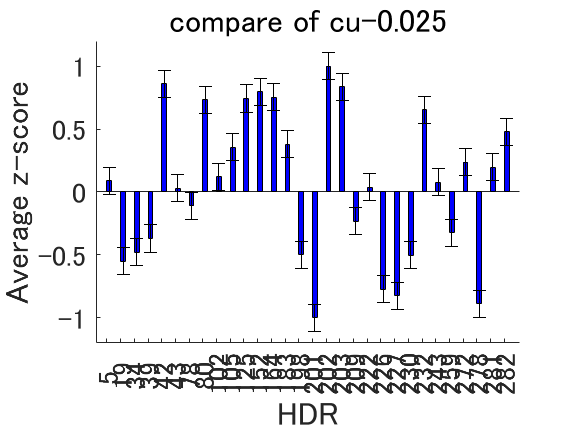

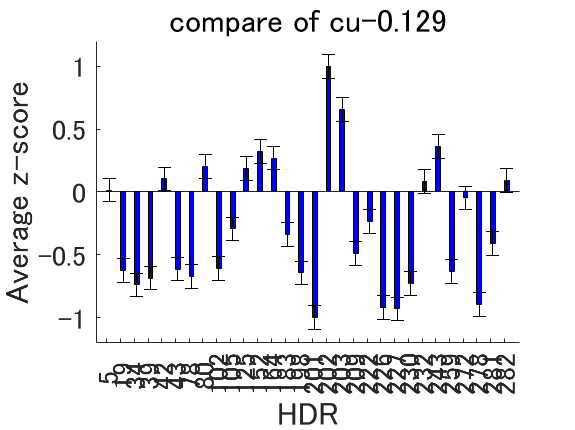

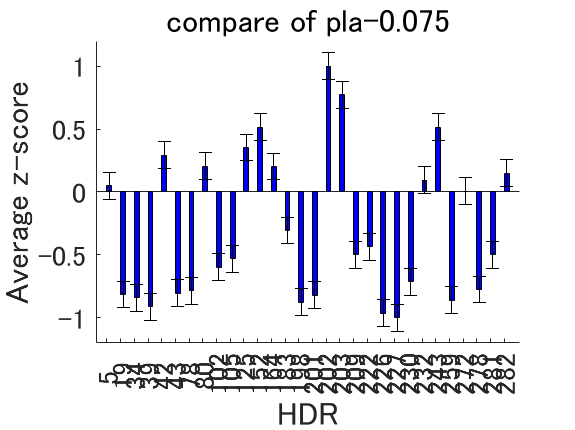

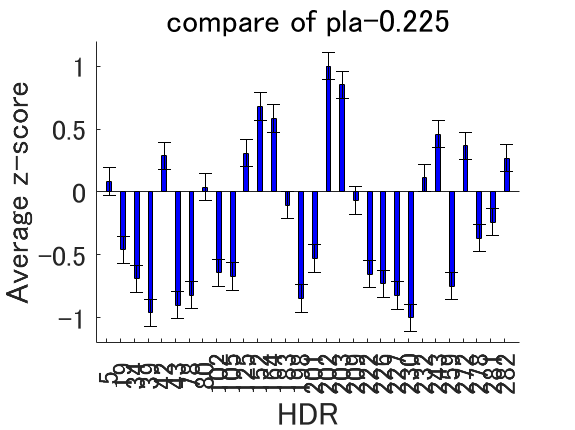

%% 1. 実験条件・照明環境ごとの選好尺度値（被験者平均）
% activate at ' exp3_analysis '
%-----------------Initialization------------------
clear all;
load('./inouedata/reshaped/z_psvList.mat')

load('./inouedata/reshaped/z_conditionList.mat')
condition_exp2 = experiment_condition;

ana_result = "analysis/";
colNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
%-----------------Setting------------------
searchColumn = [1,3];
%-----------------Analyze------------------
groupColumns = condition_exp2(:, searchColumn);

columnCells = num2cell(groupColumns, 1);
[groupIdx, uniqueGroups1,uniqueGroups2] = findgroups(columnCells{:});

groupMeans = splitapply(@(x) mean(x, 1), psv_experiment2, groupIdx);

%正規化
NormalizedData = zeros(size(groupMeans));
for i = 1:size(groupMeans,1)
    row_min = min(groupMeans(i, :));
    row_max = max(groupMeans(i, :));
    
    NormalizedData(i, :) = 2 * (groupMeans(i, :) - row_min) / (row_max - row_min)-1;
end

name = strcat(uniqueGroups1,'-', uniqueGroups2);

error_exp3 = std(NormalizedData, 0, 2)/ sqrt(size(NormalizedData, 2));
error_exp3 = repmat(error_exp3, 1, 30);
for row = 1:size(NormalizedData,1)
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, NormalizedData(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    h3 = errorbar(x + bar_width/2, NormalizedData(row, :), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' name{row}], 'FontSize', 16);

    plotname = strcat(ana_result, '/I_', name{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

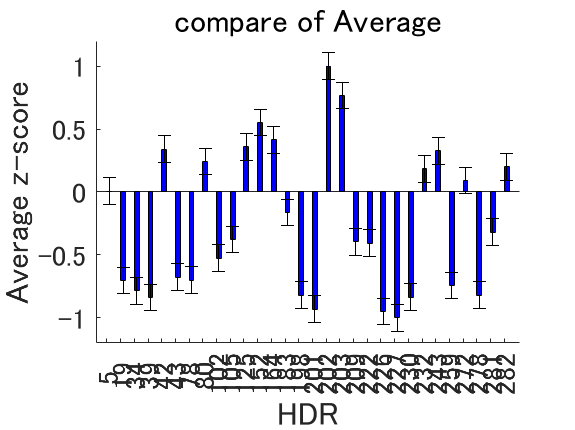


% Av graph
AvgroupsMeans = mean(groupMeans, 1);
%正規化
Av_Noromalized = zeros(size(AvgroupsMeans));
for i = 1:size(AvgroupsMeans,1)
    row_min = min(AvgroupsMeans(i, :));
    row_max = max(AvgroupsMeans(i, :));
    
    Av_Noromalized(i, :) = 2 * (AvgroupsMeans(i, :) - row_min) / (row_max - row_min)-1;
end

error_av = std(Av_Noromalized, 0, 2)/ sqrt(size(Av_Noromalized, 2));
error_av = repmat(error_av, 1, 30);

figure;
hold on;
bar_width = 0.35;
x = 1:length(colNames);
avb = bar(x + bar_width/2, Av_Noromalized, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, Av_Noromalized, error_av, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(colNames));
set(gca, 'XTickLabel', colNames, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Average z-score', 'FontSize', 16);
title('compare of Average', 'FontSize', 16);
plotname = strcat(ana_result, '/I_Average.jpg');
saveas(gcf, plotname);
hold off;